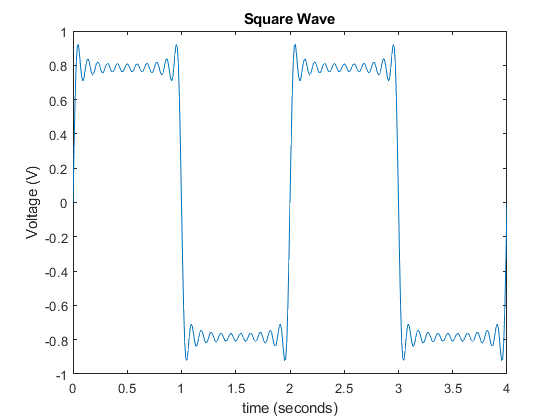

%{
Generating sq. wave, by fourier series expansion

EEE2001 NETWORK THEORY - Digital Assignment 1
19BEE1050, RITHVIK NISHAD
----------------------------------------------------
%}

% Get square wave parameters:
A       = 5; %= input('Square Wave Amplitude (V)       : ')
T       = 2; %= input('Enter Time Period (s)           : ')
y       = 0; %= input('Enter DC offset (V)             : ')

% Get compute parameters: 
cycles  = 2; %= input('No. of cycles to plot           : ')
n_max   = 10;%= input('Enter number of terms to compute: ')

w = 2 * pi / T;
t = 0 : .01 : ( T * cycles );

% perform fourier series expansion
for n = 0 : n_max
    y = y + ( sin( (2*n+1) * w * t ) / (2*n+1) );
end

% plot the equivalent
figure
plot(t, y)
title('Square Wave')
xlabel('time (seconds)')
ylabel('Voltage (V)')